# Plot experimental data

Use the Matlab code below to download and plot the measurement data.

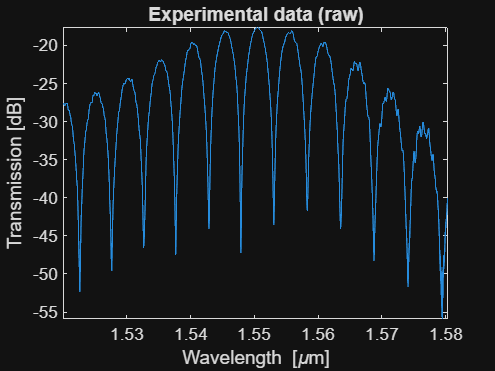

% Enter the Dropbox URL here.  Make sure it has a =1 at the end:
url = 'https://www.dropbox.com/s/1rvjfef4jqybc12/ZiheGao_MZI2_271_Scan1.mat?dl=1';
PORT=1; % Which Fibre array port is the output connected to?

a=websave('a.mat',url); % get data from Dropbox
load('a.mat');

% Data is stored in variable "scanResults".
% There are two columns - wavelength (1), and amplitude (2)
lambda=scanResults(1,PORT).Data(:,1)/1e9;
amplitude=scanResults(1,PORT).Data(:,2);

% Plot the raw data:
figure;
plot (lambda*1e6, amplitude);
xlabel ('Wavelength [\mum]');
ylabel ('Transmission [dB]');
axis tight
title ('Experimental data (raw)');